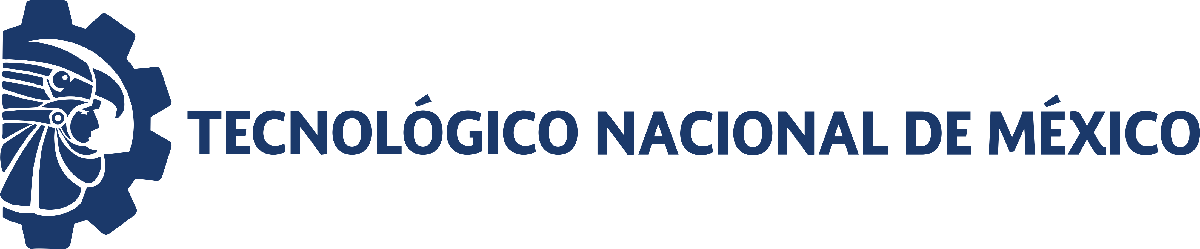                                 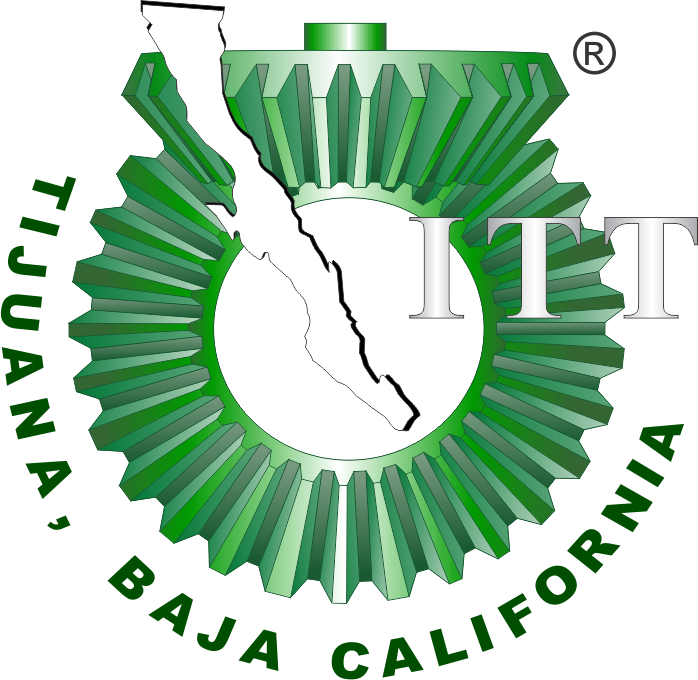

# Práctica dos: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

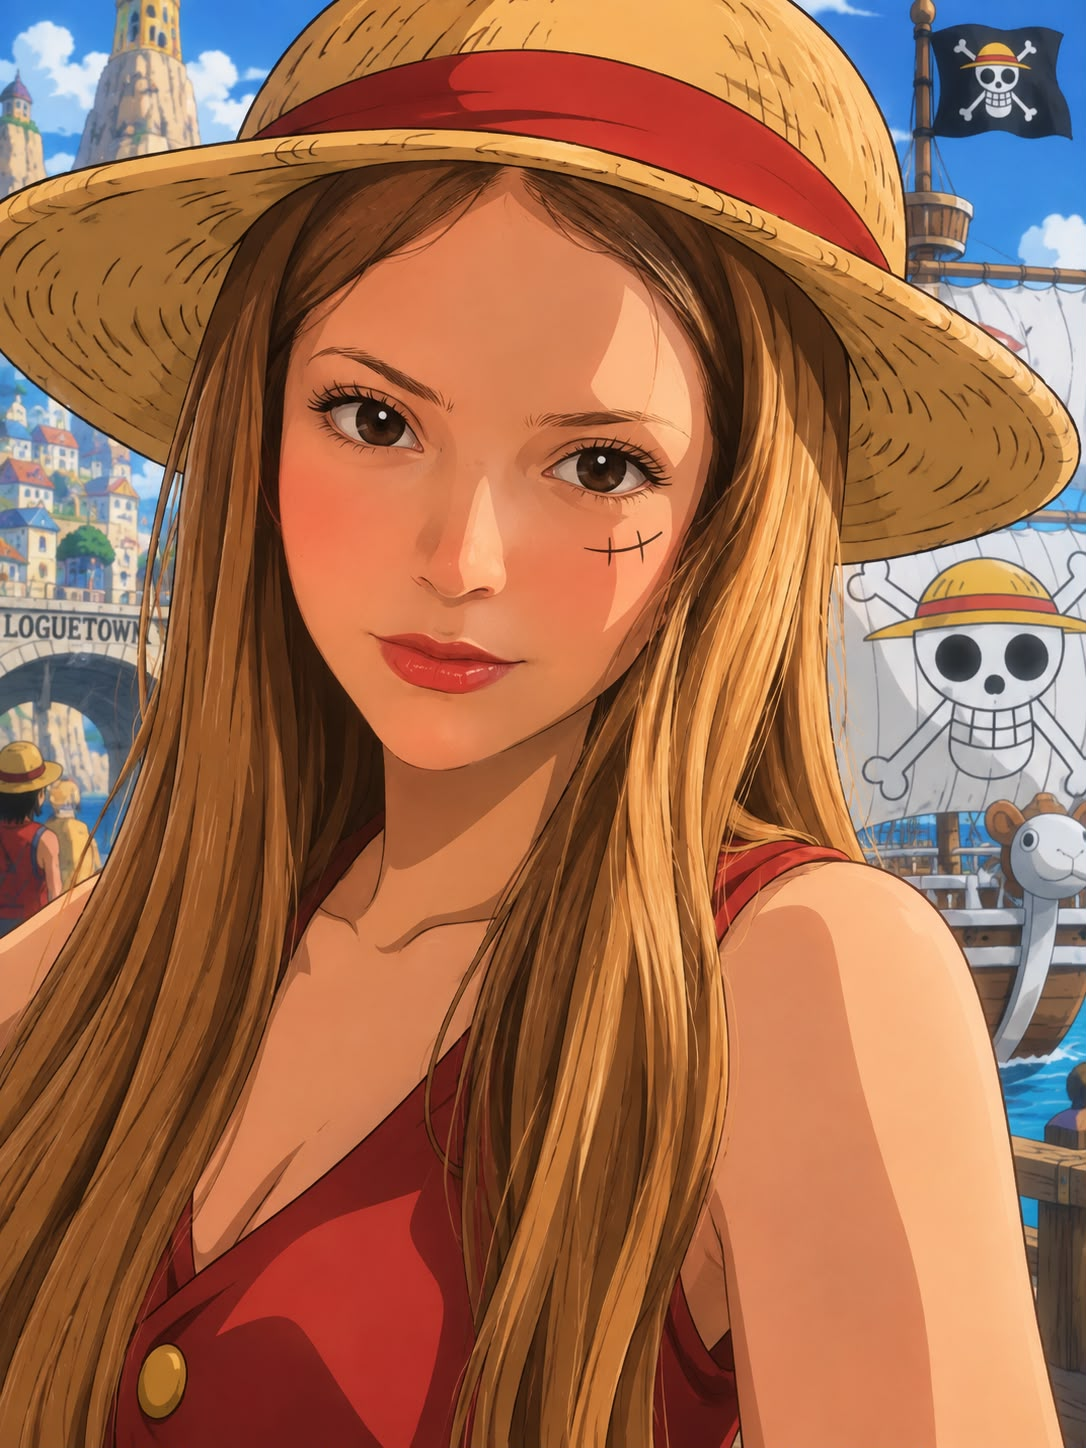

Nombre del alumno: **Ibarra Monroy Ivana Valeria**

Número de control: 23210709

Correo institucional: l23210709**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('ibarra2321070902')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('ibarra2321070902',parameters);
writematrix(x.Pa, 'signal.xlsx')

## Respuesta: Hipotenso, Normotenso, hipertenso

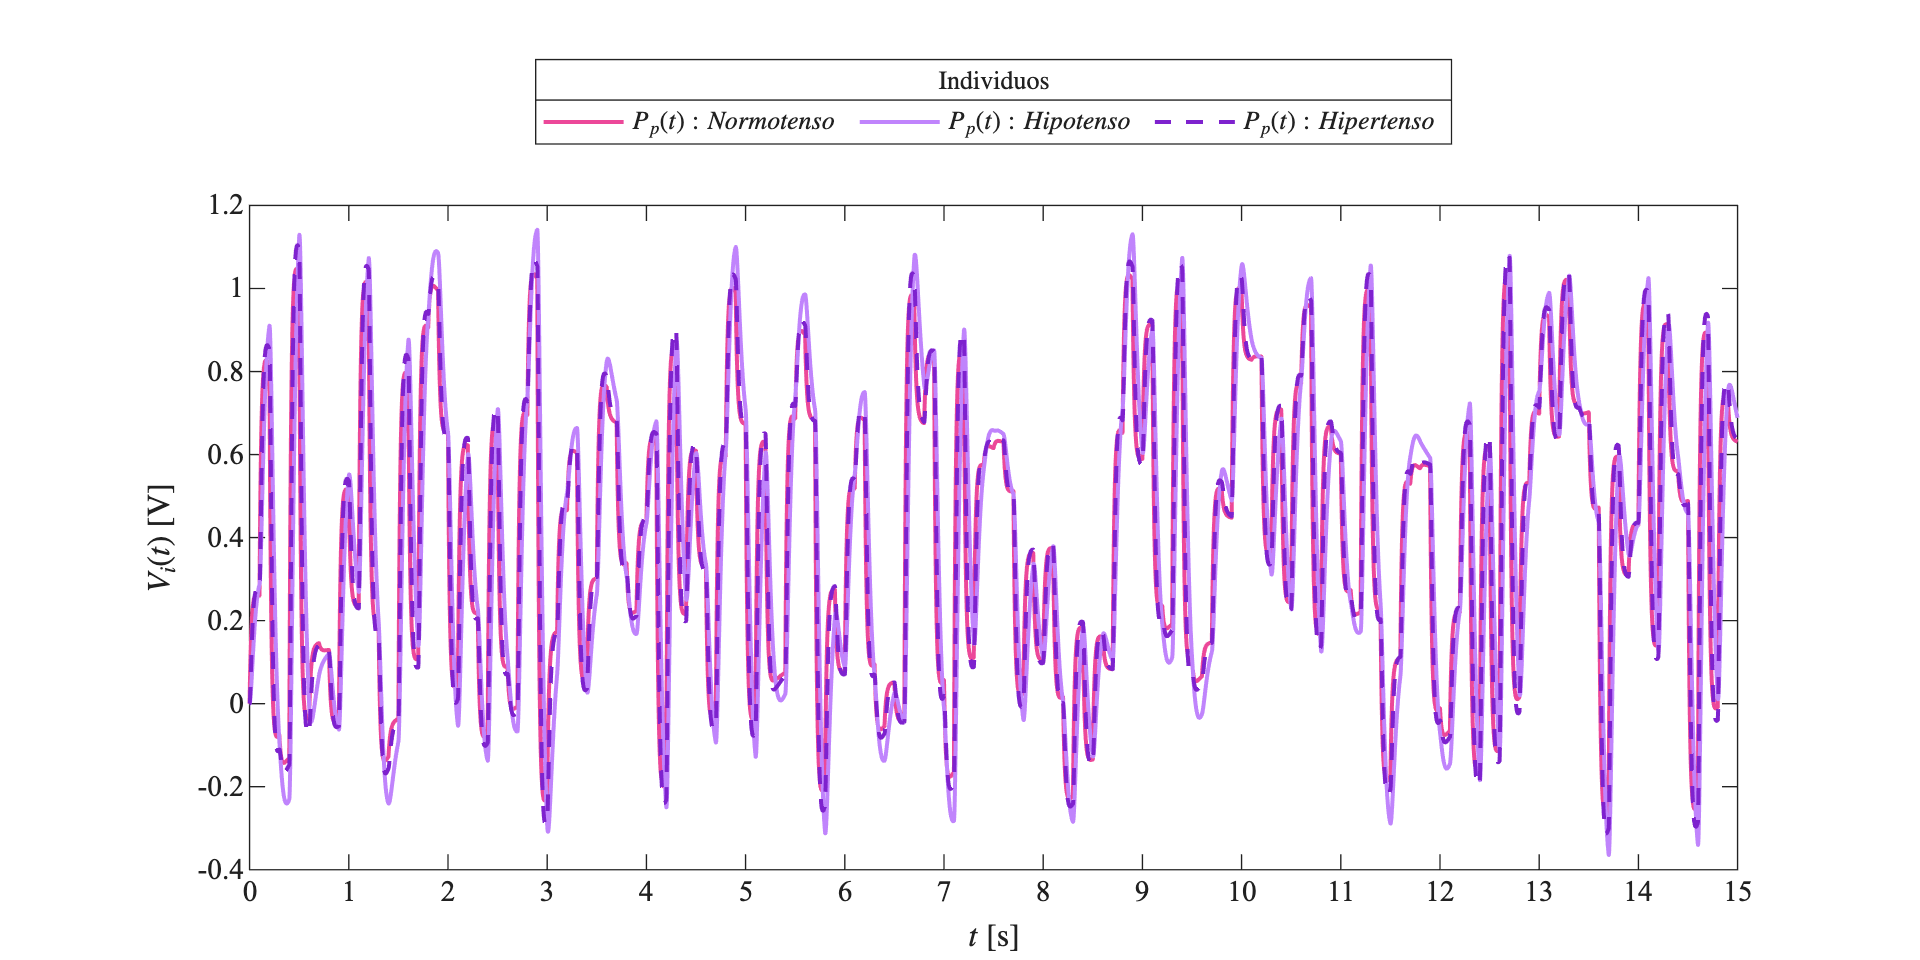

plotsignals(x.t,x.PpN,x.PpL,x.PpH,'Individuos')

## Respuesta: Hipotenso, Normotenso, hipertenso

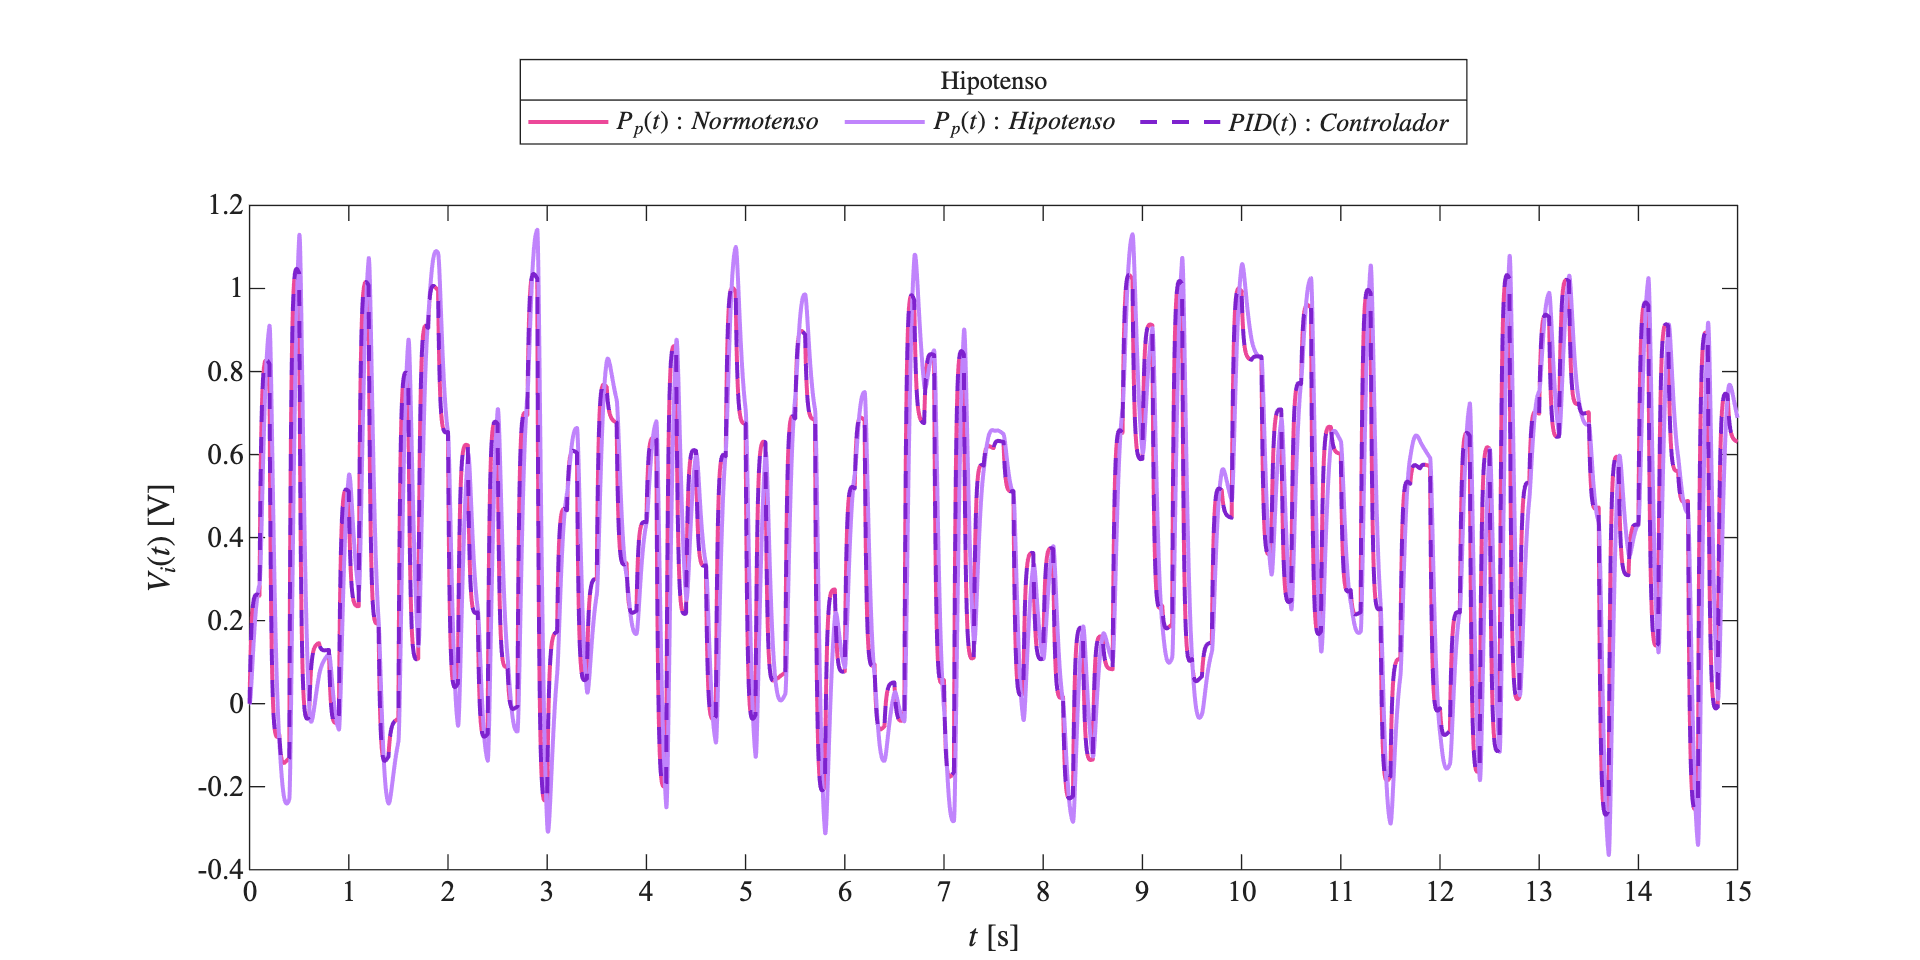

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuesta: Hipotenso, Normotenso, hipertenso

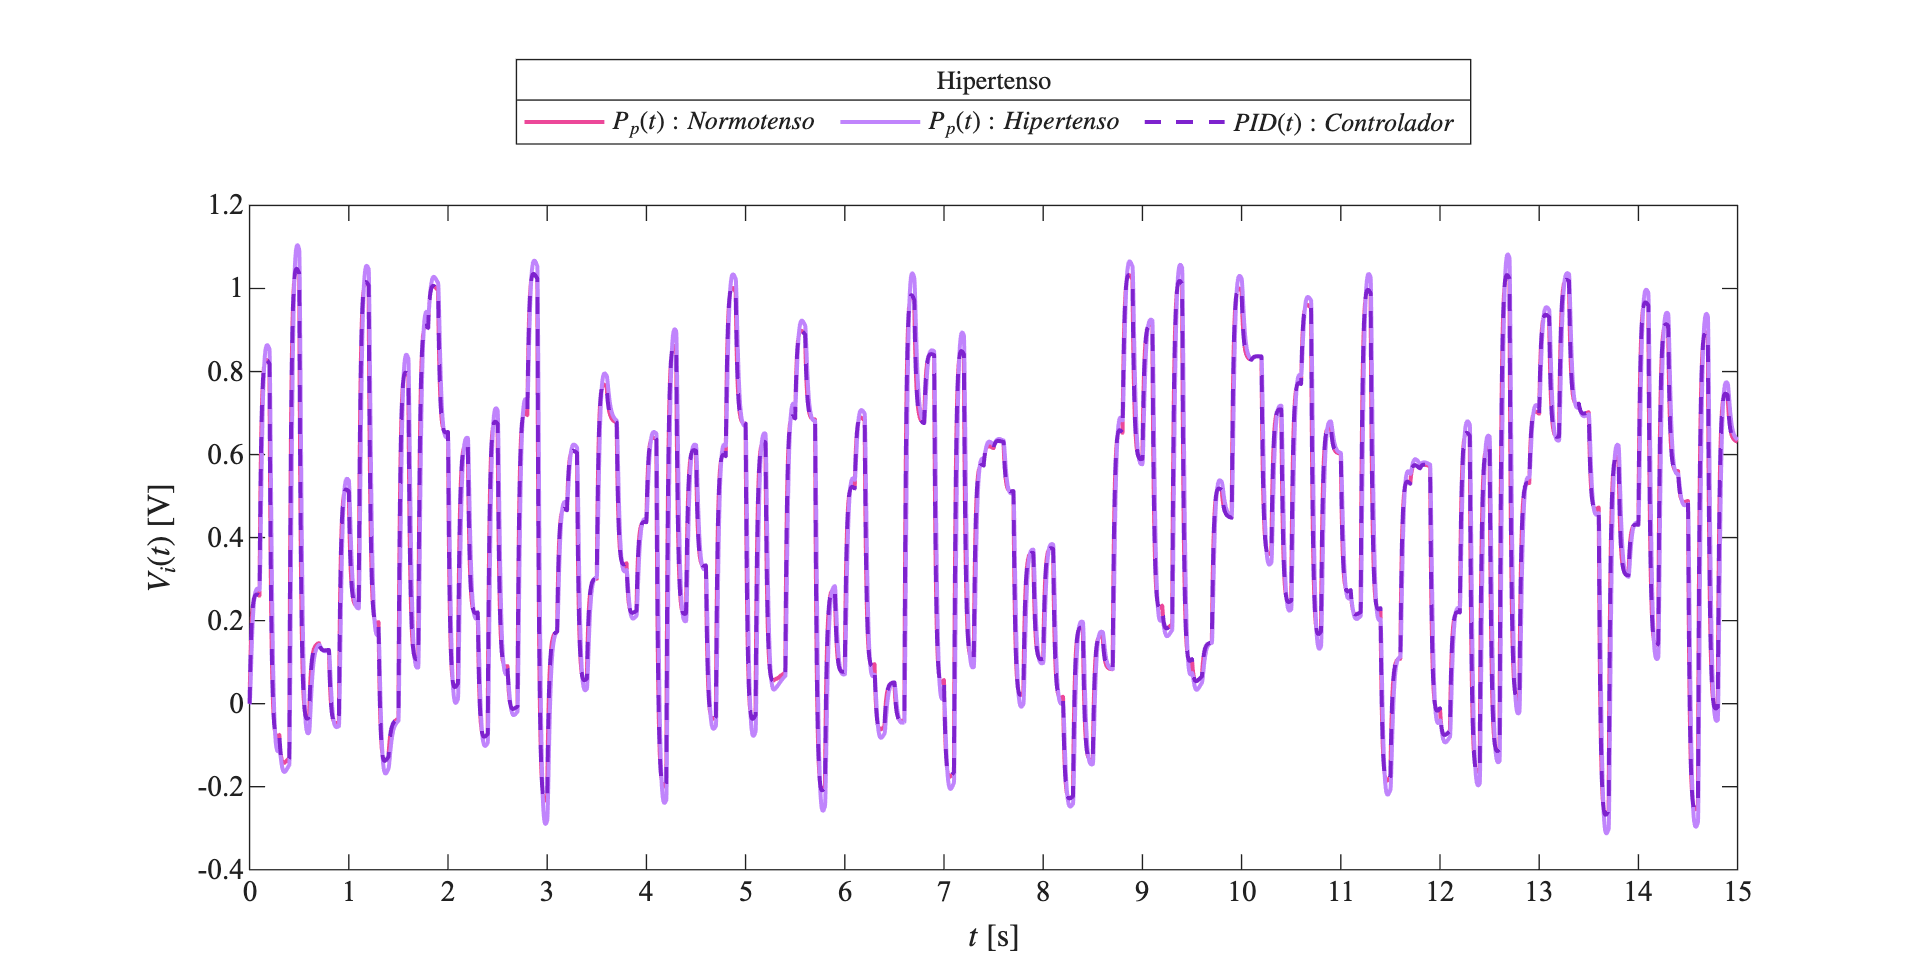

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

## Funcion: Respuestas de las senales 

function plotsignals(t,x1,x2,x3,caso)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [236,72,153]/255;
clr2 = [192,132,252]/255;
clr3 = [126,34,206]/255;
colororder([clr1;clr2;clr3])
plot(t,x1,'-',t,x2,'-',t,x3,'--', ...
    'LineWidth',1.5);
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$V_i(t)$ [V]','Interpreter','latex')
xlim([0 15]); xticks(0:1:15)
ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
if caso == "Individuos"
    L = legend('$P_p(t): Normotenso$', ...
        '$P_p(t): Hipotenso$', ...
        '$P_p(t): Hipertenso$');
elseif caso == "Hipotenso"

    L = legend('$P_p(t): Normotenso$', ...
        '$P_p(t): Hipotenso$', ...
        '${PID}(t): Controlador$');
elseif caso == "Hipertenso"

    L = legend('$P_p(t): Normotenso$', ...
        '$P_p(t): Hipertenso$', ...
        '${PID}(t): Controlador$');
end
set(L,'interpreter','latex', ...
    'location','northoutside', ...
    'orientation','horizontal')
title(L,caso)

exportgraphics(gcf,[caso,'_matlab.pdf'], ...
    'contenttype','vector')

end